clear;
addpath(genpath('attacks'));
addpath(genpath('libraries'));

image.name = "uva.bmp";

disp(["image: ", image.name]);

    "image: "    "uva.bmp"




image.path.original = strcat("images/", image.name);
image.path.watermarked = strcat("watermarkedProf/", image.name);
image.path.attacked = strcat("attacked/", image.name);

image.original = imread(image.path.original);
image.watermarked = imread(image.path.watermarked);

image.attacksBoundaries.precision = 1;
image.attacksBoundaries.values = getAttacksBoundaries(image);

    "attack: "    "awgn"

    "attack: "    "blur"

    "attack: "    "jpeg"

    "attack: "    "resize"



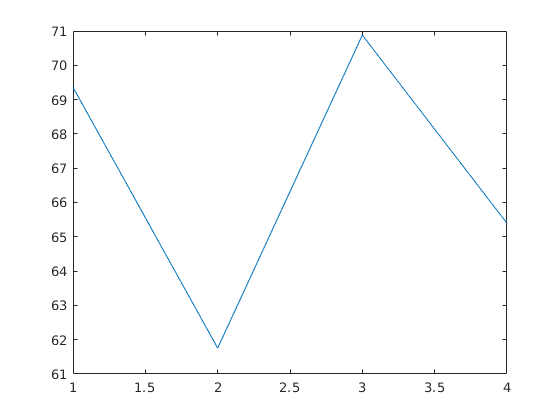


plot(1:size(image.attacksBoundaries.values), image.attacksBoundaries.values(:, 1));


%{
disp("multi attack");

set = @(x)setAux(x, image);

foundState.power = 0;
[foundState.watFound, foundState.wpsnr] = set(foundState.power);
if ~foundState.watFound
    disp("watermark not found with minimum power");
end

lostState.power = 1;
[lostState.watFound, lostState.wpsnr] = set(lostState.power);
if lostState.watFound
    disp("watermark found with maximum power");
end

while foundState.wpsnr - lostState.wpsnr > image.attacksBoundaries.precision
    tempState.power = (lostState.power + foundState.power)/2;
    [tempState.watFound, tempState.wpsnr] = set(tempState.power);
    if tempState.watFound
        foundState = tempState;
    else
        lostState = tempState;
    end
end

function [watFound, wpsnr] = setAux(power, image)
    imwrite(multiAttack(image, power), image.path.attacked, "bmp");
    [watFound, wpsnr] = detectionProf(image.path.original, image.path.watermarked, image.path.attacked);
end
%}